beta = 0.1; % Set beta
lambdareport = 1; % Where to report V_tot/E_inf at

lambda = 1e-10:0.001:5; % Range of lambdas
energies = arrayfun(@(x) getV(x, beta), lambda); % Compute V(lambda, beta)

% Report the value of V_tot/E_inf at lambdareport
disp(['For lambda = ',num2str(lambdareport),', V_tot/E_inf = ',num2str(getV(lambdareport, beta))])

For lambda = 1, V_tot/E_inf = -1.1296


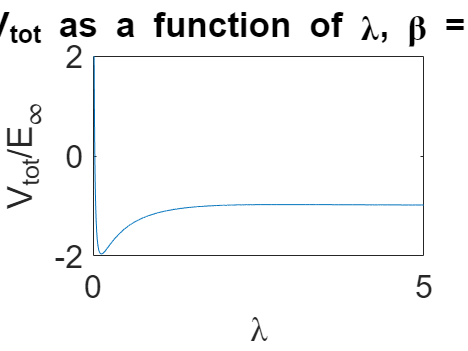


% Create the plot
p=plot(lambda,energies);
p.Parent.FontSize = 16;
title(['V_{tot} as a function of \lambda, \beta = ',num2str(beta)]);
xlabel('\lambda');
ylabel('V_{tot}/E_{\infty}');
axis([0,5,-2,2]);


% Function to compute the total energy at a given lambda and beta
% % See if we can find a minimum
% [~, pos] = findpeaks(-energies); % -energies to find minima instead of maxima
% [~, numpoints] = size(lambda);
% if pos < numpoints % Make sure that we didn't just find the last point
%     hold on;
%     plot(lambda(pos), energies(pos),'ro');
%     hold off;
%     disp(['Found a minimum at lambda = ',num2str(lambda(pos)),' and V_tot/E_inf = ',num2str(energies(pos))]);
% end
beta = 0.31; % Set beta
lambdareport = 0.41;
lambdareport2 = 0.40;
lambdareport3 = 0.395;

lambda = 1e-10:0.001:5; % Range of lambdas
energies = arrayfun(@(x) getV(x, beta), lambda); % Compute V(lambda, beta)

% Report the value of V_tot/E_inf at lambdareport
disp(['For lambda = ',num2str(lambdareport),', V_tot/E_inf = ',num2str(getV(lambdareport, beta))])

For lambda = 0.41, V_tot/E_inf = -1.0254


% Report the value of V_tot/E_inf at lambdareport2
disp(['For lambda = ',num2str(lambdareport2),', V_tot/E_inf = ',num2str(getV(lambdareport2, beta))])

For lambda = 0.4, V_tot/E_inf = -1.0255


% Report the value of V_tot/E_inf at lambdareport3
disp(['For lambda = ',num2str(lambdareport3),', V_tot/E_inf = ',num2str(getV(lambdareport3, beta))])

For lambda = 0.395, V_tot/E_inf = -1.0254


function val = getV(lambda, beta)
    % Perform a root finding operation to obtain the value of xi(lambda)
    xi = fzero(@(xi) f(xi,lambda),0.5);
    % Return the energy V/E_inf
    % You have variables beta, xi and lambda available to use
    val = beta/lambda-xi^2/lambda^2;
end

% Function that we want to find the root of
function val = f(xi,lambda)
    val = xi/(1+exp(-2*xi))-lambda;
end